# Interconnected systems

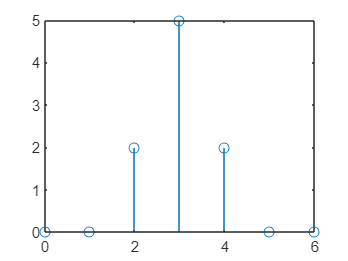

clear variables
x = @(n)(n==0);
n = 0:6;
y = 2*x(n-2) + 5*x(n-3) + 2*x(n-4);
figure; stem(n,y);

## LTI system

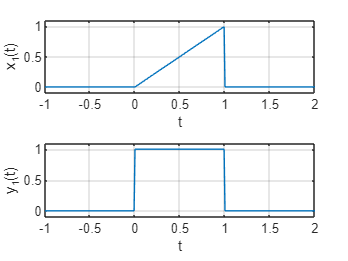

u = @(t)(t >= 0);
x1 = @(u,t)((u(t)-u(t-1)).*t);
t = -1:0.01:3;
subplot(211); plot(t,x1(u,t)); axis([-1 2 -0.1 1.1]); grid;
xlabel('t'); ylabel('x_1(t)');
y1 = @(u,t)(u(t)-u(t-1));
subplot(212); plot(t,y1(u,t)); axis([-1 2 -0.1 1.1]); grid;
xlabel('t'); ylabel('y_1(t)');


x2 = x1(u,t)+x1(u,t-1); figure; subplot(211); plot(t,x2);
axis([-1 3 -0.1 1.1]); grid; xlabel('t'); ylabel('x_2(t)');

y2 = y1(u,t)+y1(u,t-1); subplot(212); plot(t,y2);
axis([-1 3 -0.1 1.1]); grid; xlabel('t'); ylabel('y_2(t)');

x=@(t)(-1*((t>=-1)&(t<0)) + (1-t).*((t>=0)&(t<1)) + (4-2*t).*((t>=1)&(t<2)))

x = function_handle with value:
    @(t)(-1*((t>=-1)&(t<0))+(1-t).*((t>=0)&(t<1))+(4-2*t).*((t>=1)&(t<2)))


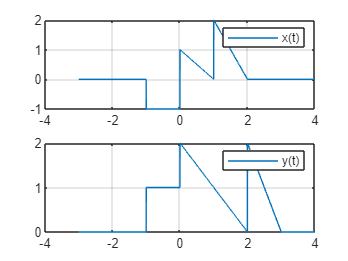

t=-3:0.001:4; y = abs(x(t)-x(t-1));
subplot(2,1,1), plot(t,x(t)),legend('x(t)'); grid;
subplot(2,1,2), plot(t,y),legend('y(t)'); grid;